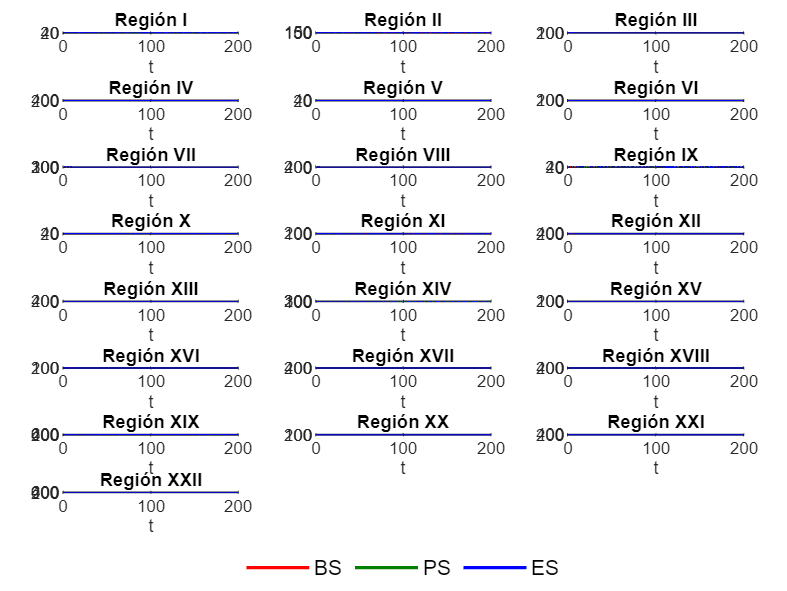

% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Parámetros del sistema
alpha1_val = 0.00137;
beta1_val = 0.07;
gamma1_val = 0.01;
mu1_val = 0.01;
alpha2_val = 0.0011;
beta2_val = 0.29;
gamma2_val = 0.01;
mu2_val = 0.01;
alpha3_val = 0.001;
beta3_val = 0.1;
tau_val = 0.0995;
C_val = 146.9;

% Condiciones iniciales
x0 = [15.4667; 0.0790; 8.9326]; % Ajusta según tu sistema
tspan = [0, 200];

% Definir las ecuaciones del sistema
dx = @(t, x, theta1_val, theta2_val) [
    (alpha1_val * x(1) * (C_val - x(1) - x(2) - x(3))) / (1 + gamma1_val * x(3)) - x(1) * (beta1_val + mu1_val * x(3)-theta1_val);
    (alpha2_val * x(2) * (C_val - x(1) - x(2) - x(3)) * (1 + tau_val * x(1))) / (1 + x(3) * gamma2_val) - x(2) * (beta2_val + mu2_val * x(3)- theta2_val);
    alpha3_val * x(3) * (C_val - x(1) - x(2) - x(3)) - beta3_val * x(3)
];

% Valores de eta para cada región
theta1_values = [0.0218, 0.083, 0.25, 0.6, 0.0218, 0.105, 0.28, 0.5, 0.03, 0.033, 0.16, 0.36, 0.5, 0.04, 0.2, 0.25, 0.42, 0.48, 0.05, 0.26, 0.6, 0.8];
theta2_values = [0.0642, 0.0642, 0.0642, 0.0642, 0.1542, 0.1542, 0.1542, 0.1542, 0.22, 0.268, 0.3, 0.35, 0.35, 0.48, 0.55, 0.46, 0.6, 0.65, 0.8, 0.8, 0.8, 0.8];
region_titles = {'Región I', 'Región II', 'Región III', 'Región IV', 'Región V', 'Región VI', 'Región VII', 'Región VIII', 'Región IX', 'Región X', 'Región XI', 'Región XII', 'Región XIII', 'Región XIV', 'Región XV', 'Región XVI', 'Región XVII', 'Región XVIII','Región XIX','Región XX','Región XXI','Región XXII'};

% Crear figura con distribución clara
figure;
t = tiledlayout(8, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% Títulos de regiones (ya definidos antes)
for i = 1:length(theta1_values)
    theta1_val = theta1_values(i);
    theta2_val = theta2_values(i);

    % Resolver el sistema
    [t_sol, x] = ode45(@(t, x) dx(t, x, theta1_val, theta2_val), tspan, x0);

    % Crear subplot limpio
    nexttile;
    plot(t_sol, x(:,1), '-r', 'LineWidth', 1.5); hold on;
    plot(t_sol, x(:,2), 'Color', [0, 0.5, 0], 'LineWidth', 1.5);
    plot(t_sol, x(:,3), '-b', 'LineWidth', 1.5); hold off;

    title(region_titles{i}, 'FontSize', 10);
    xlabel('t');
    ylabel('Población');
    grid on;
    ax = gca;
    ax.FontSize = 8;
end

% Texto global al final
lgd = legend({'BS', 'PS', 'ES'}, 'Orientation', 'horizontal', ...
    'Box', 'off', 'FontSize', 10, 'Location', 'southoutside');
lgd.Layout.Tile = 'south';